%% Description

% This program draws equidensity lines.



%% Housekeeping
addpath('C:\Users\Parth Patel\Documents\GitHub\Image-Processing\Matlab-Functions-Image-Processing');

%% Load a sample data file
image_info.name = '02-12-2016_21_18_37_top.fits';
image_info.path = fullfile('D:\Dropbox Sync\Dropbox (MIT)\BEC1\Image Data and Cicero Files\Data - Raw Images\2016\2016-02\2016-02-12',image_info.name);
disp(image_info.path);

D:\Dropbox Sync\Dropbox (MIT)\BEC1\Image Data and Cicero Files\Data - Raw Images\2016\2016-02\2016-02-12\02-12-2016_21_18_37_top.fits


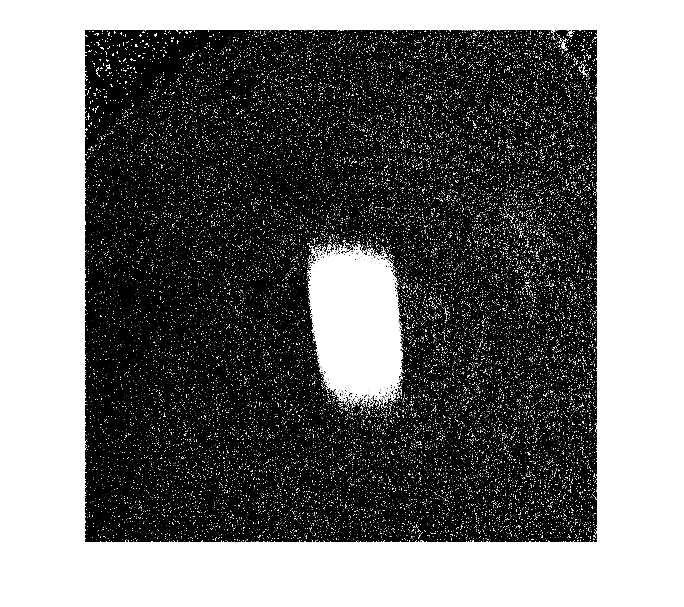

[~,image_info.alldata] = load_img(image_info.path); 
image_info.OD = image_info.alldata{1};
image_info.wa = image_info.alldata{3};
image_info.woa = image_info.alldata{4};
image_info.dark = image_info.alldata{5};
imshow(image_info.OD,[0 0.05]); set(gca,'YDir','normal');

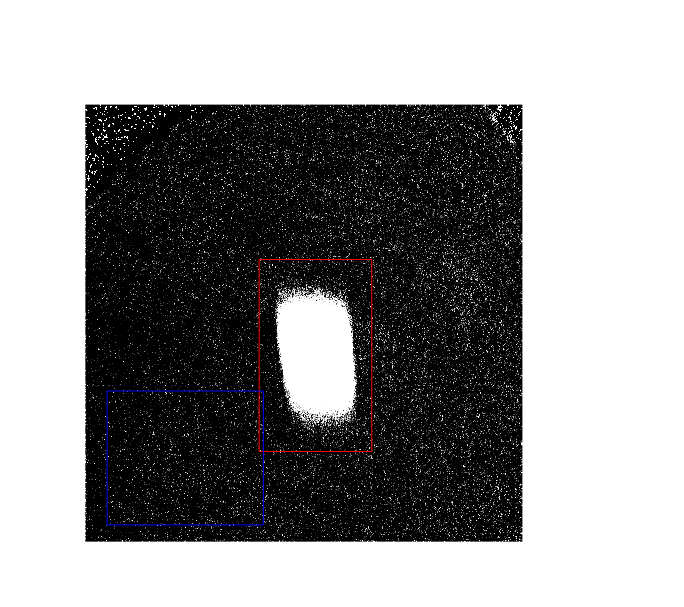

%% Clean up image
image_info.roi_rect = [204,106,132,225]; % [xmin ymin width height]
image_info.roi_data = imcrop(image_info.OD,image_info.roi_rect);
if 0 || ~isfield(image_info,'roi_rect'), [image_info.roi_data,image_info.roi_rect] = imcrop(image_info.OD); end % [204.51,106.51,131.98,210.98]
image_info.bg_rect = [26,20,183, 157];
image_info.bg_data = imcrop(image_info.OD,image_info.bg_rect);
if 0 || ~isfield(image_info,'bg_rect'), [image_info.bg_data,image_info.bg_rect] = imcrop(image_info.OD); end % [26,20,183, 157]

figure; hold on;
imshow(image_info.OD,[0 0.1]); set(gca,'YDir','normal');
rectangle('Position',image_info.roi_rect,'FaceColor','none','EdgeColor','red'); 
rectangle('Position',image_info.bg_rect,'FaceColor','none','EdgeColor','blue'); hold off;

image_info.bg_value = mean(image_info.bg_data(:));
image_info.cleanOD = image_info.roi_data - image_info.bg_value;
disp(['Backgroun subtracted: ', num2str(image_info.bg_value)]);

Backgroun subtracted: -0.065835


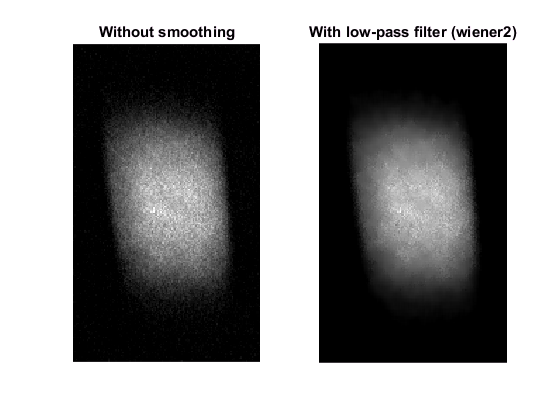

%% Contour plotting
figure;
image_info.smoothdata = wiener2(image_info.roi_data,[6 6]);
subplot(1,2,1); imshow(image_info.roi_data,[0,1.5]); set(gca,'YDir','normal'); title('Without smoothing');
subplot(1,2,2); imshow(image_info.smoothdata,[0 1.5]); set(gca,'YDir','normal'); title('With low-pass filter (wiener2)');

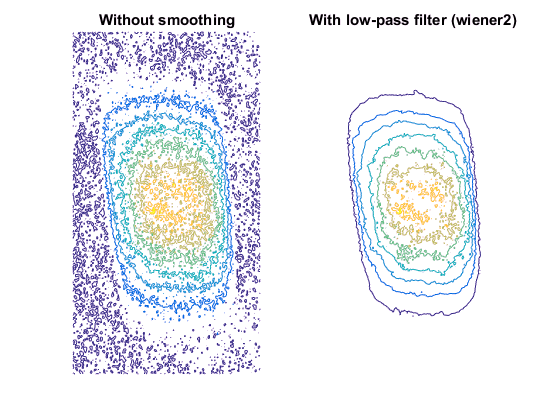

figure;
subplot(1,2,1); contour(image_info.roi_data,8); axis off; title('Without smoothing');
subplot(1,2,2); contour(image_info.smoothdata,8); axis off; title('With low-pass filter (wiener2)');

%% Correct for Tilt
